# EV simulation backward approach

clc
clear

% Vehicle Input Paramater
M=1710 % Max loaded mass (kg)

M = 1710

H=1598 % Car height (mm)

H = 1598

L=2570 % Car wheel base (mm)

L = 2570

hg=0.30*H % Car CG height (mm)

hg = 479.4000

la=0.48*L % Car CG distance from front wheel (mm)

la = 1.2336e+03

lb=L-la % Car CG distance from rear wheel (mm)

lb = 1.3364e+03


% Inertia detail

% Typical rotor inertia:
% 150 kW IPM/PMSM: ~0.06–0.12
% 150 kW Induction (IM): ~0.08–0.18
% 200 kW IPM/PMSM: ~0.08–0.16
% 200 kW Induction (IM): ~0.10–0.25

Jr=0.07 % Rotor inertia (kg/m2)

Jr = 0.0700

Jgb=0.02 % Gear box inertia (kg/m2)

Jgb = 0.0200

Jw= 0.05 % Wheel inertia (kg/m2)

Jw = 0.0500


% Rotation damping detail
Bl=0.25 % (N/m.s.rad)

Bl = 0.2500


Cd=0.25 % Aerodynamic drag coefficient

Cd = 0.2500

Cr=0.011 % Rolling resistance

Cr = 0.0110

Af=1.775*1.598 % Front area of car (m2)

Af = 2.8365

eff_g=0.95 % Efficiency of gear driveline

eff_g = 0.9500

eff_m=0.90 % Efficiency of traction motor

eff_m = 0.9000

GR=11 % Transmission gear ratio

GR = 11


% Tire input paramater
%           W  AR D_in 
Tire_spec=[225 45 17]

Tire_spec =    225    45    17


H_tire=Tire_spec(1)*Tire_spec(2)/100  % Tire height (mm)

H_tire = 101.2500

R_tire=(Tire_spec(3)*25.4+2*H_tire)/2 % Free static radius of tire (mm) 

R_tire = 317.1500

R_w=round(0.98*R_tire) % Effective radius of tire (mm)

R_w = 311


% Battery input paramater
eff_b=0.97 % Efficiency of battery

eff_b = 0.9700

C=4.8*12 % Battery cell rated capacity 1C (Ah)

C = 57.6000

U_pack=360 % Battery pack nominal voltage (V)

U_pack = 360

I_pack=432 % Battery pack continuous current (A)

I_pack = 432

U_bat=3.6 % Battery cell nominal voltage (V)

U_bat = 3.6000

U_min=2.5 % Battery cell minimum voltage (V)

U_min = 2.5000

U_max=4.1 % Battery cell maximum voltage (V)

U_max = 4.1000

I_max=9.6 % Max discharge current (continuous) (A)

I_max = 9.6000

I_peak=25 % Peak current (30 sec) (A)

I_peak = 25

m_cell=0.069 % Battery cell mass (kg)

m_cell = 0.0690

D_cell=0.0211 % Battery cell diameter (mm)

D_cell = 0.0211

H_cell=0.07015 % Battery cell height (mm)

H_cell = 0.0702

R_cell=0.02 % Battery cell internal resistance (ohm)

R_cell = 0.0200


% Physical paramater
pho_air=1.295 % Density of air (kg/m3)

pho_air = 1.2950

g=9.81 % Acceleration due to gravity (m/s2)

g = 9.8100


% Road paramater
Grd=0 % Road gradient

Grd = 0


% Vehicle performance paramaters
L_range=235 % Expected Max range (km)

L_range = 235

V_max=150 % Max car speed (kmph)

V_max = 150

V_max_grad=100 % Max car speed on 5% slope road (kmph)

V_max_grad = 100

V_max_climb=10 % Car speed on 33% slope road (kmph)

V_max_climb = 10

t_acc=7.3 % Time for acceleration from 0 to 100 kmph (sec)

t_acc = 7.3000

t_top=220 % Time for reaching top speed (sec)

t_top = 220

t_duty_cycle=1800

t_duty_cycle = 1800


% Duty cycle case

duty_cycle_case=[1,2,3]

duty_cycle_case =      1     2     3


time = 1800

ans =   Simulink.SimulationOutput:

           Data_logging: [180001x3 double] 
                   tout: [180001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


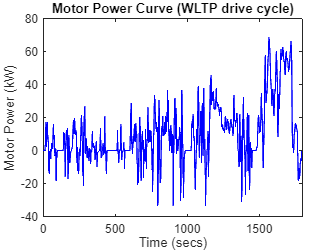

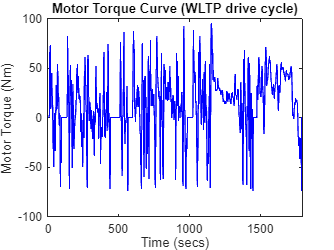

time = 7.3000

ans =   Simulink.SimulationOutput:

           Data_logging: [731x3 double] 
                   tout: [731x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


time = 220

ans =   Simulink.SimulationOutput:

           Data_logging: [22001x3 double] 
                   tout: [22001x1 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


for i=0:duty_cycle_case(end)
    if i==1   % WLTP drive cycle
       time=t_duty_cycle  
       sim("EV_sim_model.slx")
       motor_speed_1=ans.Data_logging(:,1);
       motor_torque_1=ans.Data_logging(:,2);
       motor_power_1=ans.Data_logging(:,3);

       figure(1)
       plot(ans.tout,motor_power_1,"b")
       ylabel("Motor Power (kW)", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")
       title("Motor Power Curve (WLTP drive cycle)")
       xlabel("Time (secs)", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")
       xlim([0 t_duty_cycle])
       
       figure(2)
       plot(ans.tout,motor_torque_1,"b")
       ylabel("Motor Torque (Nm)", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")
       title("Motor Torque Curve (WLTP drive cycle)")
       xlabel("Time (secs)", "FontName", "Helvetica", "FontAngle", "normal", "FontWeight", "normal")
       xlim([0 t_duty_cycle])

    elseif i==2  % Acceleration drive cycle
       time=t_acc
       sim("EV_sim_model.slx")
       Max_torque=max(ans.Data_logging(:,2));

    elseif i==3  % Top speed drive cycle
       time=t_top
       sim("EV_sim_model.slx")
       Max_power=max(ans.Data_logging(:,3));
       Max_speed=max(ans.Data_logging(:,1));
    end    
end

open("EV_sim_model.slx")

Max_speed_c=ceil(Max_speed/500)*500

Max_speed_c = 15500

Max_torque_c=ceil(Max_torque/50)*50

Max_torque_c = 250

Max_power_c=ceil(Max_power/25)*25

Max_power_c = 125

# Motor curve plotting code

% Parameter of traction motor
N_em_max=Max_speed_c; % Max speed in RPM
T_em_peak=Max_torque_c; % Peak torque in Nm
P_em_max=Max_power_c; % Peak power in kW
N_em_b=0.40*N_em_max; % Base speed in RPM
P_em_cont=0.55*P_em_max; % Continous power in kW

N_em_min=0; % Min speed in RPM
dN_em=500; % Division of speed axis
eff_min=0.75;  % Min efficiency
eff_max=0.95; % Max efficiency

%Loss parameter of EM
kc=0.25; %Copper loss coefficient
ki=0.01; %Iron loss coefficient
kw=0.000005; %Windage loss coefficient
C=600; %constant power losses

% Pre calculation of Peak power and Continous torque
T_em_cont=P_em_cont*1000/(N_em_b*pi/30);
P_em_peak=T_em_peak*pi*N_em_b/30/1000;

% Slope calculation of power 
Slope_cont=P_em_cont/N_em_b;
Slope_peak=P_em_peak/N_em_b;

N_em=linspace(N_em_min,N_em_max,dN_em);
N_em=transpose(N_em);

l=length(N_em);

% Generation of Power curve
P_em_cont_y=zeros(l,1);
P_em_peak_y=zeros(l,1);

for i=1:length(N_em)
    if N_em(i)<=N_em_b
        P_em_cont_y(i)=Slope_cont*N_em(i);
        P_em_peak_y(i)=Slope_peak*N_em(i);
    else
        P_em_cont_y(i)=P_em_cont;
        P_em_peak_y(i)=P_em_peak;
    end
end

% Generation of Torque curve
T_em_cont_y=zeros(l,1);
T_em_peak_y=zeros(l,1);

for i=1:length(N_em)
    if N_em(i)<=N_em_b
        T_em_cont_y(i)=T_em_cont;
        T_em_peak_y(i)=T_em_peak;
    else
        T_em_cont_y(i)=P_em_cont_y(i)*1000/(N_em(i)*pi/30);
        T_em_peak_y(i)=P_em_peak_y(i)*1000/(N_em(i)*pi/30);
    end
end


% Efficiency map calculation
N_em_eff=linspace(N_em_min,N_em_max,dN_em);
T_em_eff=linspace(0,T_em_peak,dN_em);

P_out=zeros(dN_em,dN_em);
P_loss=zeros(dN_em,dN_em);

for i=1:length(N_em_eff)
    for j=1:length(T_em_eff)
        P_out(i,j)=T_em_eff(j)*pi*N_em_eff(i)/30;
        P_loss(i,j)=kc*T_em_eff(j)^2+ki*pi*N_em_eff(i)/30+kw*(pi*N_em_eff(i)/30)^3+C; 
    end
end
eff_em= P_out./(P_loss+P_out);
eff=min(eff_max,max(eff_min,eff_em))*100;

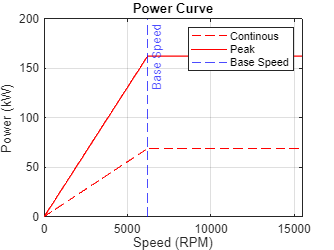


%Plotting Part

%Power curve
figure(3)
plot(N_em,P_em_cont_y,'r--')
hold on
plot(N_em,P_em_peak_y,'r')
hold off
title('Power Curve')
xlabel("Speed (RPM)")
ylabel("Power (kW)")
legend('Continous','Peak')
xline(N_em_b,'b--','Base Speed')
grid on
legend(["Continous", "Peak", "Base Speed"])

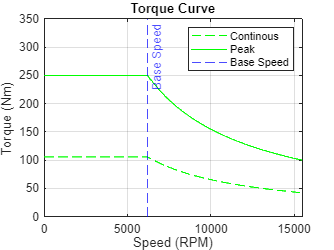


%Torque curve
figure(4)
plot(N_em,T_em_cont_y,'g--')
hold on
plot(N_em,T_em_peak_y,'g')
hold off
title('Torque Curve')
xlabel("Speed (RPM)")
ylabel("Torque (Nm)")
legend('Continous','Peak')
xline(N_em_b,'b--','Base Speed')
grid on
xlim([0 N_em_max])
ylim([0 T_em_peak+100])
legend(["Continous", "Peak", "Base Speed"])

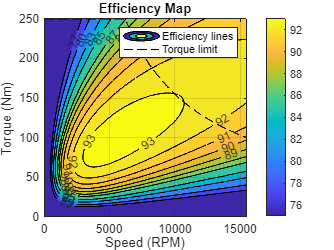



%Efficiency map
V=[50,70,73,75,77,80,83,85,87,88,89,90,91,92,93];
figure(5)
contourf(N_em_eff,T_em_eff,eff,V,'Showtext','on')
hold on
plot(N_em,T_em_peak_y,'k--')
hold off
xlabel("Speed (RPM)")
ylabel("Torque (Nm)")
xlim([0 N_em_max])
ylim([0 T_em_peak])

grid on
colorbar
title('Efficiency Map')

xlim([0 N_em_max])
ylim([0 T_em_peak])
legend(["Efficiency lines", "Torque limit"])